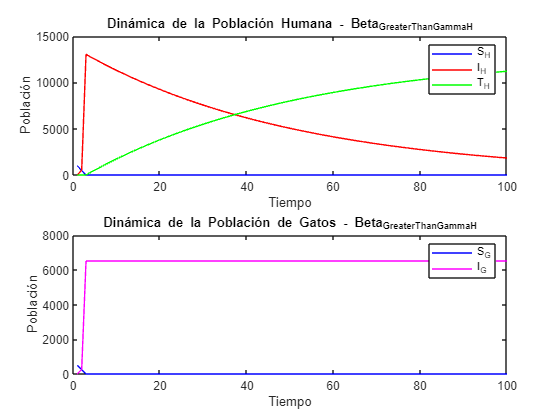

%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

              %%%PREGUNTA V%%%
           %¿QUÉ SUCEDE SI β>γH�?%

% Parámetros
beta = 0.1; % Tasa de infección
gamma_H = 0.02; % Tasa de recuperación en humanos (menor que la tasa de infección)

% Poblaciones totales
Total_H = 1000;
Total_G = 500;

% Caso a analizar
case_name = 'Beta_Greater_Than_Gamma_H';

% Inicializar poblaciones
S_H = 990; % Humanos susceptibles
I_H = 10;  % Humanos infectados
T_H = 0;   % Humanos tratados
S_G = 495; % Gatos susceptibles
I_G = 5;   % Gatos infectados

% Inicializar vectores de almacenamiento para resultados
t_max = 100;
S_H_vals = zeros(1, t_max);
I_H_vals = zeros(1, t_max);
T_H_vals = zeros(1, t_max);
S_G_vals = zeros(1, t_max);
I_G_vals = zeros(1, t_max);

% Simulación
for t = 1:t_max
    % Almacenar resultados
    S_H_vals(t) = S_H;
    I_H_vals(t) = I_H;
    T_H_vals(t) = T_H;
    S_G_vals(t) = S_G;
    I_G_vals(t) = I_G;
    
    % Calcular las derivadas
    dS_H = round(-beta * I_G * S_H);
    dI_H = round(beta * I_G * S_H - gamma_H * I_H);
    dT_H = round(gamma_H * I_H);
    
    dS_G = round(-beta * I_G * S_G);
    dI_G = round(beta * I_G * S_G);
    
    % Actualizar poblaciones
    S_H = S_H + dS_H;
    I_H = I_H + dI_H;
    T_H = T_H + dT_H;
    
    % Verificar que las poblaciones no sean negativas
    S_H = max(S_H, 0);
    I_H = max(I_H, 0);
    T_H = max(T_H, 0);
    
    S_G = S_G + dS_G;
    I_G = I_G + dI_G;
    
    % Verificar que las poblaciones no sean negativas
    S_G = max(S_G, 0);
    I_G = max(I_G, 0);
end

% Guardar resultados en la estructura
results.(case_name) = struct('S_H', S_H_vals, 'I_H', I_H_vals, 'T_H', T_H_vals, 'S_G', S_G_vals, 'I_G', I_G_vals);

% Graficar los resultados
figure;

% Dinámica de la población humana
subplot(2, 1, 1);
plot(1:t_max, S_H_vals, 'b', 'DisplayName', 'S_H');
hold on;
plot(1:t_max, I_H_vals, 'r', 'DisplayName', 'I_H');
plot(1:t_max, T_H_vals, 'g', 'DisplayName', 'T_H');
xlabel('Tiempo');
ylabel('Población');
title(['Dinámica de la Población Humana - ' case_name]);
legend;
hold off;

% Dinámica de la población de gatos
subplot(2, 1, 2);
plot(1:t_max, S_G_vals, 'b', 'DisplayName', 'S_G');
hold on;
plot(1:t_max, I_G_vals, 'm', 'DisplayName', 'I_G');
xlabel('Tiempo');
ylabel('Población');
title(['Dinámica de la Población de Gatos - ' case_name]);
legend;
hold off;


% Mostrar resultados finales para el caso actual
fprintf('Resultados finales:\n S_H = %.2f\n I_H = %.2f\n T_H = %.2f\n I_G = %.2f\n S_G = %.2f\n\n', S_H, I_H, T_H, I_G, S_G);

Resultados finales:
 S_H = 0.00
 I_H = 1797.00
 T_H = 11231.00
 I_G = 6502.00
 S_G = 0.00




% Cálculo del Número de Reproducción Básico (R0)
R0 = beta / gamma_H;
fprintf('Número de Reproducción Básico (R0): %.2f\n', R0);

Número de Reproducción Básico (R0): 5.00



% Proporción final de infectados
proportion_infected_humans = T_H / Total_H;
fprintf('Proporción final de humanos infectados y tratados: %.2f%%\n', proportion_infected_humans * 100);

Proporción final de humanos infectados y tratados: 1123.10%



% Pico de la epidemia
[max_infected_humans, peak_time_humans] = max(I_H_vals);
fprintf('Pico de la epidemia en humanos: %d infectados en el tiempo %d\n', max_infected_humans, peak_time_humans);

Pico de la epidemia en humanos: 13018 infectados en el tiempo 3



[max_infected_gatos, peak_time_gatos] = max(I_G_vals);
fprintf('Pico de la epidemia en gatos: %d infectados en el tiempo %d\n', max_infected_gatos, peak_time_gatos);

Pico de la epidemia en gatos: 6502 infectados en el tiempo 3



% Duración de la epidemia (cuando el cambio en infectados es cero o insignificante)
threshold = 0.01; % Umbral para el cambio insignificante
epidemic_duration_humans = t_max; % Valor por defecto si no se encuentra un cambio insignificante
epidemic_duration_gatos = t_max; % Valor por defecto si no se encuentra un cambio insignificante

for t = 2:t_max
    if abs(I_H_vals(t) - I_H_vals(t-1)) < threshold
        epidemic_duration_humans = t;
        break;
    end
end

for t = 2:t_max
    if abs(I_G_vals(t) - I_G_vals(t-1)) < threshold
        epidemic_duration_gatos = t;
        break;
    end
end

fprintf('Duración de la epidemia en humanos: %d pasos discretos\n', epidemic_duration_humans);

Duración de la epidemia en humanos: 100 pasos discretos


fprintf('Duración de la epidemia en gatos: %d pasos discretos\n', epidemic_duration_gatos);

Duración de la epidemia en gatos: 4 pasos discretos
